clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref



% param.ctrl.ks(:,:,1) =[-0.0669, 0.3820, 0.0769];
% param.ctrl.ks(:,:,2) = [-0.0390, 0.2228, 0.0449];
% param.ctrl.ks(:,:,3) = [-0.0334, 0.1910, 0.0385];
% param.ctrl.ks(:,:,4) =[-0.0557,0.3184, 0.0641];

simtime = 10*60;

## Control

param.ctrl.Ks = control.DesignProcedure1(param);

++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                Constraint|    Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality 12x12|   0.024977 to 6.0379|
|   #2|   Matrix inequality 12x12|               1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++
 
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|          Constraint|   Primal residual|   Dual residual|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality|           0.67845|      1.1188e-11|
|   #2|   Matrix inequality|           0.63434|      2.3963e-12|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals.|
| In practice, many solvers converge to slightly infeasible    |
| solutions, which may cause some residuals to be negative.    |
| It is up to the user to judge the importance and impact of   |
| 

ans =   -77.1630
  -26.0450
   -0.3370
  -99.1562
  -20.5467
   -0.3382
 -106.6903
  -18.7980
   -0.3386
  -84.7761


Linear matrix variable 16x16 (symmetric, real, 25 variables)
Coefficient range: 0.0076484 to 916.2408
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                    Constraint|       Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|       Matrix inequality 16x16|   0.0076484 to 916.2408|
|   #2|       Matrix inequality 12x12|                  1 to 1|
|   #3|   Element-wise inequality 1x1|                  1 to 1|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
 
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|        Matrix inequality|       -1.0869e-10|        0.012052|
|   #2|        Matrix inequality|        3.7745e-11|         0.05225|
|   #3|   Elementwise inequality|       -9.1196e-14|        2405.102|
++++++++++++++++++++++++++++

ans = -9.1196e-14

ans = 1.0e-08 *

    0.0038
    0.0046
    0.0064
    0.0075
    0.0255
    0.0277
    0.0313
    0.0324
    0.1918
    0.2170


ans =   -1.0053 + 5.3915i
  -1.0053 - 5.3915i
  -0.9139 + 4.9989i
  -0.9139 - 4.9989i
  -0.6350 + 3.8674i
  -0.6350 - 3.8674i
  -0.7520 + 4.3499i
  -0.7520 - 4.3499i
  -0.3392 + 0.0000i
  -0.3399 + 0.0000i


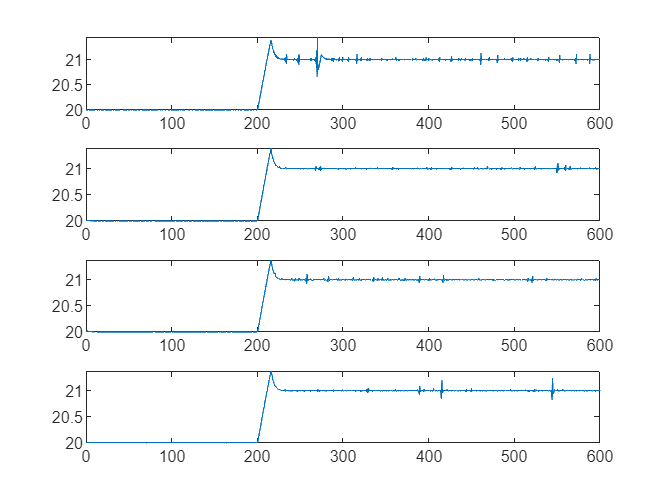

for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode45(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);
end
figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15)
end

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
options = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0,options);

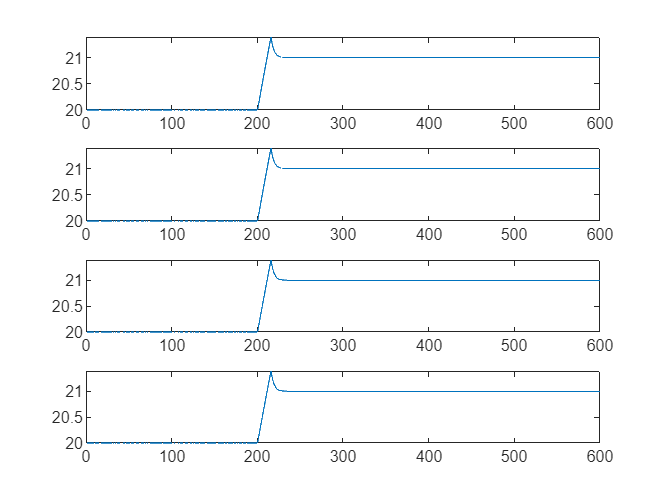

coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);

figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(coupledResults.time,coupledResults.Ta(:,1)-273.15)
end